# Peta naloga

## Statična karakteristika

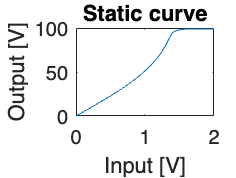

clear all;
close all;
T = 0.01;

% Definicija parametrov
N = 300;
% Definicija parametrov
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
T = 0.01;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

% Zanka za različne vrednosti V
for V = 0:dV:2
    u = ones(N, 1) * V;

    % Inicializacija stanja
    x = [0, 0];

    % Inicializacija izhodnega vektorja
    y = zeros(N, 1);

    % Simulacija helicrane
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u(i), x);

        % Posodobitev stanja
        x = [fip_, fi_];

        % Shranjevanje izhoda
        y(i) = fi_;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    y_m = mean(y(100:end));

    % Shranjevanje rezultata v c
    c(round(V/dV) + 1) = y_m;
end

% Risanje rezultata
figure;
plot(0:dV:2, c);
title("Static curve");
xlabel("Input [V]");
ylabel("Output [V]");

## APRBS signal



% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

idinput requires System Identification Toolbox.

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);
d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal

% Časovni vektorji
t_train = (0:padding + N_APRBS - 1) * T;
t_test = (0:padding + N_APRBS - 1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Training APRBS signal");
xlabel("Time [s]");
ylabel("Input [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Time [s]");
ylabel("Input [V]");

## Neural network

X_train = u_train(1:end-1)';
Y_train = u_train(2:end)';

X_test = u_test(1:end-1)';
Y_test = u_test(2:end)';

% Definicija nevronske mreže
hiddenLayerSize = 8;
net = feedforwardnet([hiddenLayerSize, hiddenLayerSize]);

% Priprava podatkov za treniranje
trainData = [X_train; Y_train];

% Konfiguracija nevronske mreže
net = configure(net, X_train, Y_train);

% Trenutje nevronske mreže
[net, tr] = train(net, X_train, Y_train);

% Testiranje nevronske mreže
Y_pred_train = net(X_train);
Y_pred_test = net(X_test);

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(t_train(2:end), Y_train, t_train(2:end), Y_pred_train);
title("Training Data and Network Output");
xlabel("Time [s]");
ylabel("Output [V]");
legend('Actual', 'Predicted');

subplot(2, 1, 2);
plot(t_test(2:end), Y_test, t_test(2:end), Y_pred_test);
title("Test Data and Network Output");
xlabel("Time [s]");
ylabel("Output [V]");
legend('Actual', 'Predicted');
